**REAL-TIME SPECTRUM ANALYZER**

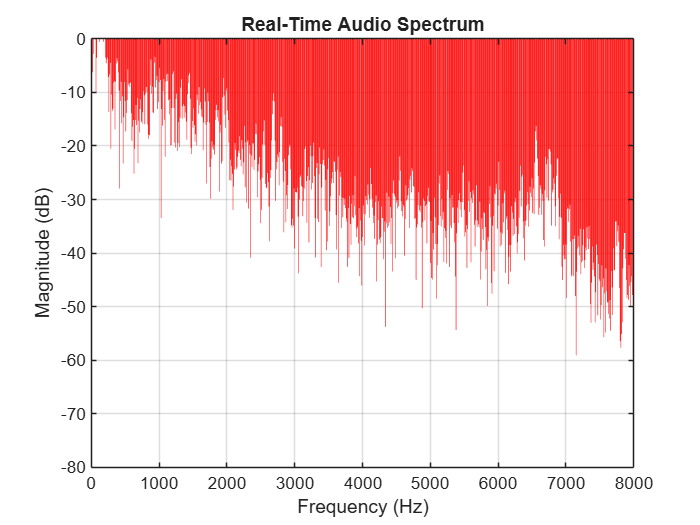

fs = 16000;
chunkLength = 0.1;
L3 = round(fs*chunkLength);
w3 = hann(L3);
f3 = (0:L3/2)*(fs/L3);

inputID = 1;
recorder = audiorecorder(fs, 16, 1, inputID);

figure(10)
hBar = bar(f3, zeros(size(f3)), 'r');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Real-Time Audio Spectrum');
axis xy;
axis([0 fs/2 -80 0]);
grid on;

record(recorder);
while true
    if recorder.TotalSamples >= L3
        dataChunk = getaudiodata(recorder);
        chunk = dataChunk(end-L3+1:end) .* w3;
        W3 = fft(chunk,L3);
        mag = 20*log10(abs(W3(1:L3/2+1)) + eps);

        set(hBar, 'YData', mag);
        drawnow;
    end
    pause(0.01);
end